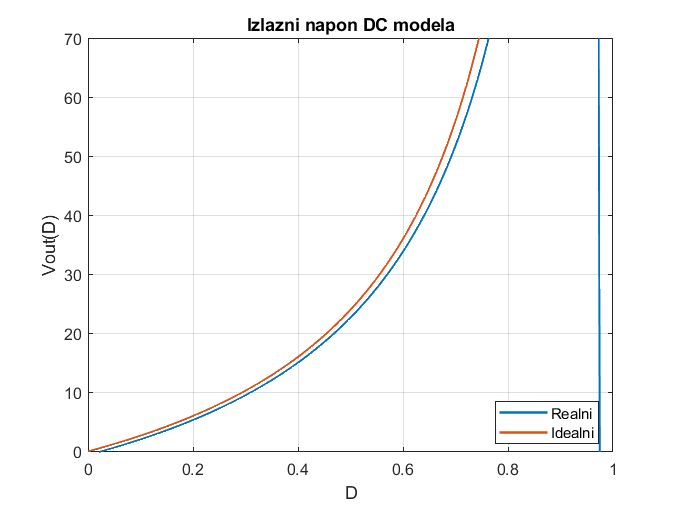

close all
clear
L=10e-6;
Cs=0.4e-6;
Co=35e-6;
rl=0.1;
rc1=0.01;
rc2=0.001;
rs=0.003;
A1=[-(rl+rs)/L, rs/L,  0,  0;rs/L, -(rs+rl+rc1)/L,  -1/L,0;0, 1/Cs, 0,  0;0, 0,  0,  0];
B1=[1/L,0;0, 0;0, 0;0, -1/Co];
C1=[0, 0,  0,  1;1,0 ,0 ,0];
D1=[0, -rc2;0 0];
A2=[-(rl+rc1+rc2+rs)/L, (rc2+rs)/L,-1/L,-1/L;(rc2+rs)/L,  -(rc2+rl+rs)/L,  0,  1/L;1/Cs,0,  0,  0;1/Co,-1/Co,0,  0];
B2=[1/L,rc2/L;0, -rc2/L;0, 0;0, -1/Co] ;
C2=[rc2, -rc2, 0,  1;1, 0, 0, 0];
D2=[0, -rc2; 0 0];
%DC operating point
% Minimalni napon
Vin=24;
Iout=6;
%Po D0
D0=0:0.001:0.999;
U0=[Vin;Iout];
Vout=zeros(1,length(D0));
for i=1:length(D0)
%Averaged matrix
A=A1*D0(i)+A2*(1-D0(i));
B=B1*D0(i)+B2*(1-D0(i));
C=C1*D0(i)+C2*(1-D0(i));
D=D1*D0(i)+D2*(1-D0(i));
%DC model
X0=-inv(A)*B*U0;
Y0=(D-C/A*B)*U0;
Vout(i)=Y0(1,1);
end
plot(D0,Vout,'LineWidth',1.5)
hold on
plot(D0,D0./(1-D0)*Vin,'LineWidth',1.5)
grid on
ylim([-0.1 70])
title('Izlazni napon DC modela')
xlabel('D')
ylabel('Vout(D)')
legend('Realni','Idealni','Location',"best")
hold off


Dnom=D0(find(Vout>=15,1))

Dnom = 0.4000

Vout(find(Vout>=15,1))

ans = 15.0393

A=A1*Dnom+A2*(1-Dnom);
B=B1*Dnom+B2*(1-Dnom);
C=C1*Dnom+C2*(1-Dnom);
D=D1*Dnom+D2*(1-Dnom);
X0=-inv(A)*B*U0

X0 =     4.0000
   -6.0000
   24.2000
   15.0393
